# EE4311 [2510] Project 1: PD Fuzzy Logic Controller

## 1 Introduction and Tasks

In project 1, we aim to design Mamdani and Sugeno fuzzy logic controllers to control an inverted pendulum on a moving cart on a slope. The controller aims to keep $\gamma$, the angle an inverted pendulum makes with the ground's perpendicular, zero, from an initial angle $\gamma_0$ where $\gamma_0 \in\{-10^\circ, -5^\circ, 5^\circ, 10^\circ\}$. The pendulum is mounted on a moving cart which is moving along an angled slope. The cart is controlled by applying a force $F$.

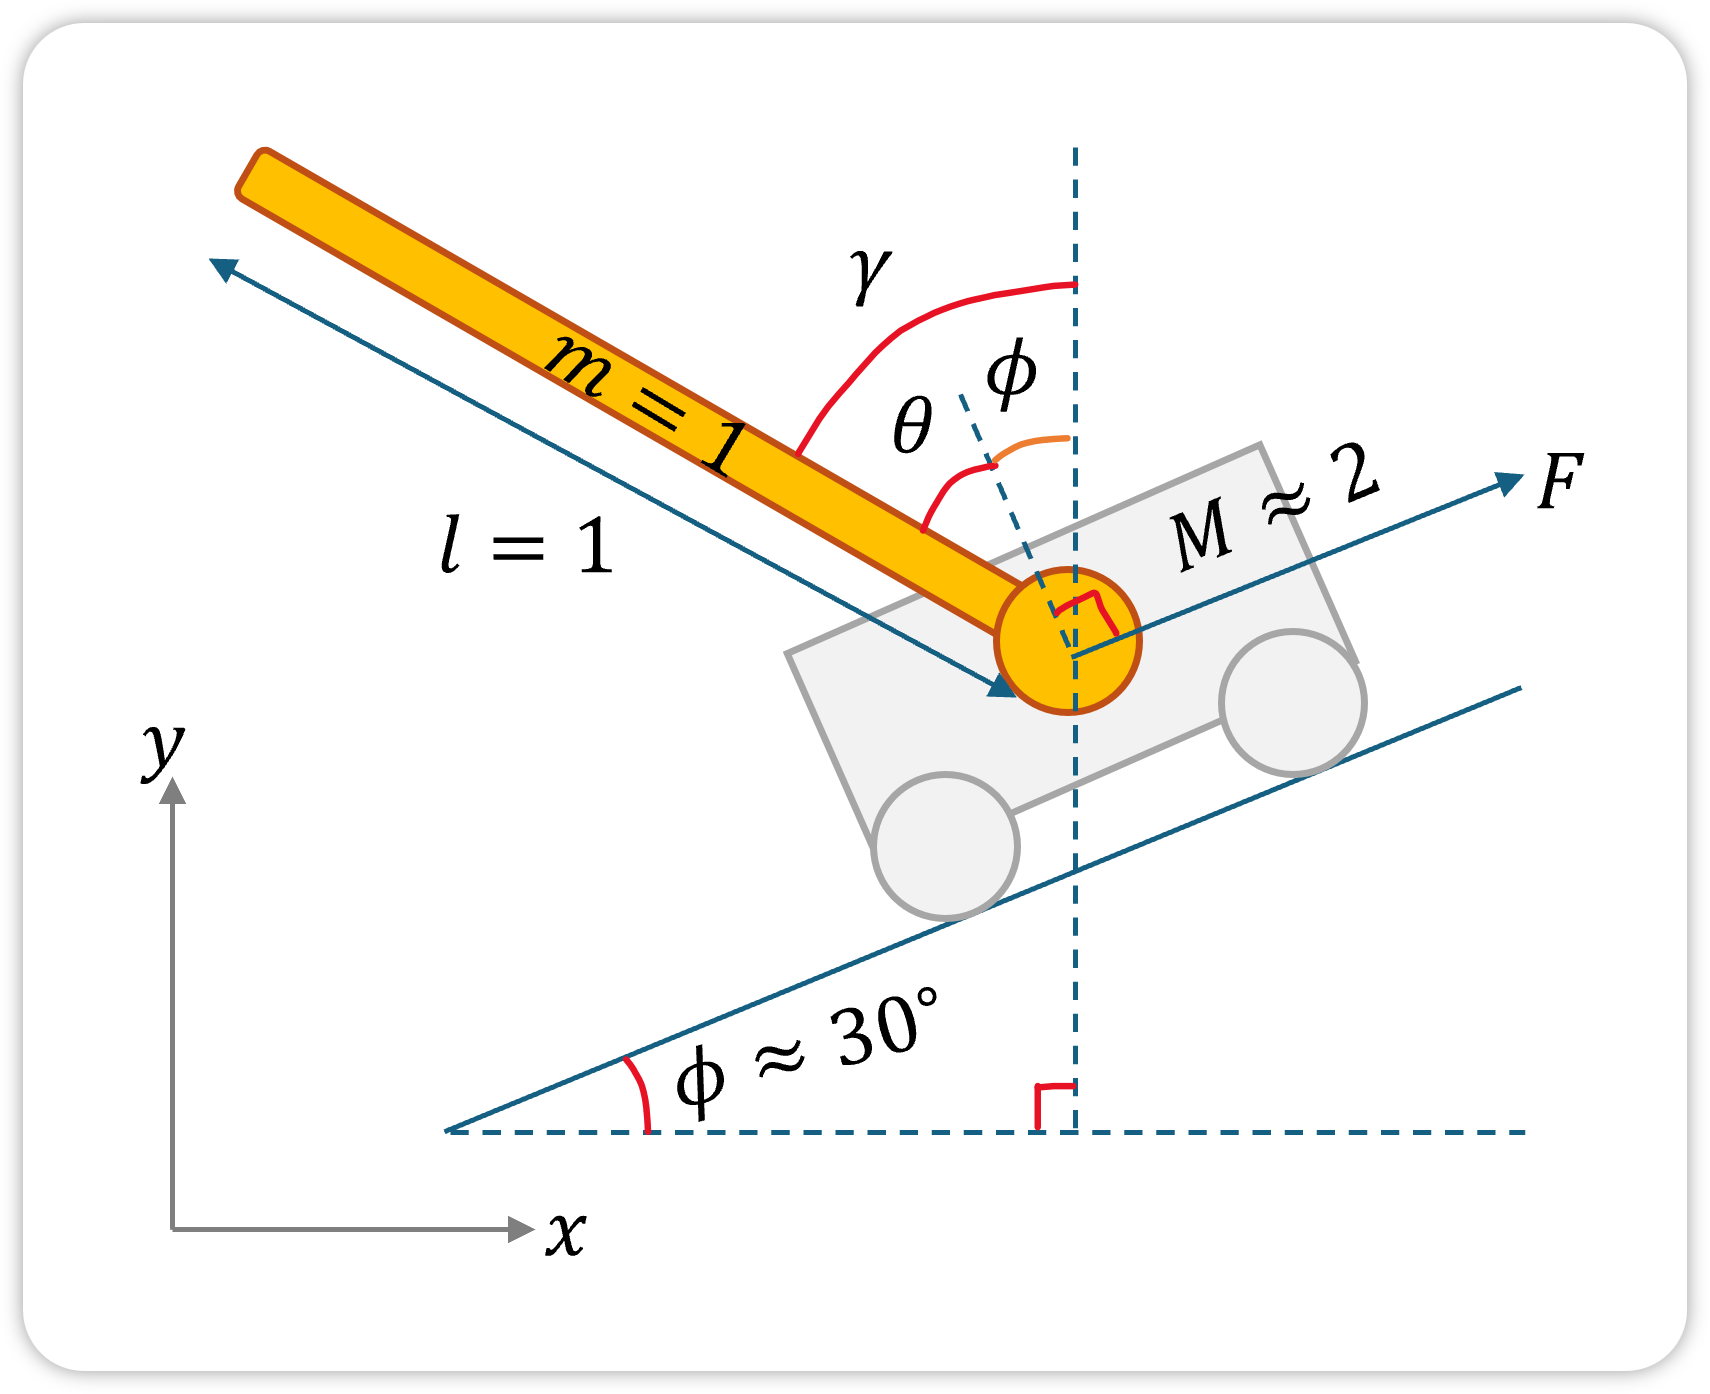

Angles are positive in the anticlockwise direction. In the image above, $\gamma>0$. A positive force $F$ moves the cart to the right of the image and up the slope. The slope angle $\phi$ and the cart body mass $M$ are randomized based on your team's matric numbers. In this worksheet, you will be introduced to several functions to build a fuzzy inference system in MATLAB. By examining the system and investigating the way the values (angles, force) change, the correct rules can be introduced and membership functions can be tuned to achieve desirable performance in Section 3. Next, adapt the code to a Sugeno system for the same PD controller.

### 1.1 `.mlx` Live Script (Mamdani)

In this worksheet, you are guided to create a Mamdani fuzzy logic controller. While no submission for the worksheet, the report should discuss the Mamdami system and show the images for the membership functions and response, as stated in the report requirements. Tuning should depend on the performance requirements in Section 3.

### 1.2 `.m` Script (Sugeno)

After the Mamdani fuzzy logic controller is built and tuned, copy the code in this worksheet to a new `.m` script to create a Sugeno fuzzy logic controller for the same problem. If you are not familiar with the steps, you can first duplicate this `.mlx` worksheet, build and tune the Sugeno fuzzy logic controller, and copy the code in the duplicated `.mlx` file into a new `.m` script file. 

- Submit `.m` format to Canvas (P1C).

- Submit as **team##.m** to avoid penalties.

- Code will be examined for plagiarism via Moss.

- All code in the `.m` script must be executable without errors.

- During the execution, images for the tuned membership function (`MFs.png`) and response (`results.png`) must be generated and saved. The `exportgraphics()` command from Section 4 should be used to do so.

- The performance requirements in Section 3 are desired.

- At least 5 term sets for each universe is used.

- The controller must use a Sugeno fuzzy inference system.

- The controller must contain at least the proportional and derivative components.

- The membership functions need not be trapezoidal.

### 1.3 `.pdf` Report

- Submit `.pdf` format to Canvas (P1R).

- Submit as **team##.pdf** to avoid penalties.

- Report will be examined for plagiarism via Turnitin.

- Excluding front matter (e.g. title page, content page) and back matter (e.g. bibliography, appendices), the report should be **about 10 pages** long. There is no limit to the page count, just make sure that the report is concise and rich of analysis

The report should:

- Contain the membership functions (`MFs.png`) and the response (`results.png`) saved by the `exportgraphics()` command in Section 4. These two images are required for both the Mamdami and Sugeno systems.

- Contain concise and ample **observations** and **explanations** on how the different parts fuzzy systems affect the behavior of the control process.

- Contain discussion for both the Mamdami and Sugeno systems. Common observations and explanations between both systems should be merged.

- State the rule table, and the values used in the membership functions.

### 1.4 `.pdf` Poster and Q&A

- Submit `.pdf` format Poster to Canvas (P1P).

- Submit as **team##.pdf** to avoid penalties.

- When requested by the assessor, every member should begin by briefly stating their contributions, and subsequently the details or insights discovered while designing and tuning the system. Every member will be scored individually, and must provide thorough evidence of work done.

- During the presentation day (which is during lecture), each team will be allowed to choose a 15-minute time slot within the lecture time to present. 

- As the presentation is held **online over Zoom**, every team must **arrive 15 minutes** before their chosen time slot until the end of Q&A.

- The Zoom link will be available on the Zoom tab on Canvas.

- It is not difficult to identify AI responses even while assessors are not able to see your screen.

### 1.5 Dates and Deadlines

- Choose your team of three by **W4 Fri**. Go to Canvas **People** $\rightarrow$ **P1 Teams** to sign up for the slots.

- All three files are to be submitted to their corresponding Canvas Assignments (P1C, P1R, P1P) on **RW Sun (28 Sep) 2359h**. 

- Choose a 15-min time slot for presentation. Go to Canvas **People** $\rightarrow$ **P1P** to choose the slot. Every member must be available for the chosen slot. The presentation will be held during lecture time and on another day depending on the number of teams. The schedule will be announced over Canvas.

## 2 Definitions

In this section, we define parameters and construct the system.

### 2.1 Initializations of Constants

To prevent too many variables from showing up (polluting) in the workspace, we gather and define constant values in the `constants` struct.

- Insert the numeric digits of your matric numbers to seed the random number generator with `rng`. This allows reproducibility of results. If a member has matric number `A0123456A` and a second member has `A0234567B` and a third has `A0345678C` then the line should look like `rng(sum([123456, 234567, 345678]))`.

clear all; close all; clc; format compact
rng(sum([123456, 765432])); % !TODO (1)

constants = struct();
constants.M_CART = rand() * 0.1 + 2; % cart mass, kg
constants.M_PEND = 1; % pend mass, kg
constants.DT = 0.01; % sim interval, s
constants.G = 9.8;
constants.CTRL_STEP = 5; % controller period = DT*CTRL_STEP
constants.L_PEND = 1; % pend length, m
constants.KF_CART = 0.3; % cart friction coeff
constants.KF_PEND = 0.4; % pend friction coeff
constants.F_MAX = 50; % max force on cart, N
constants.PHI = (rand() * 2 + 30); % slope angle, deg
constants.T_SET = 1; % settling time, s
constants.T_TOTAL = 5;
constants.GAMMA_SET = 1; % settling angle, deg
constants.DT2 = constants.DT*constants.DT;
constants.S_PHI = sind(constants.PHI);
constants.C_PHI = cosd(constants.PHI);
constants.M_TOTAL = constants.M_CART + constants.M_PEND;
constants.L76 = -constants.L_PEND * 7.0 / 6.0;
constants.MML76 = constants.M_TOTAL * constants.L76;
constants.WEIGHT = constants.G * constants.S_PHI * constants.M_TOTAL;
constants.START_GAMMAS = [-10, -5, 5, 10]; % deg

fprintf("Slope=%.3f deg; Cart mass=%.3f kg\n", constants.PHI, constants.M_CART);

Slope=31.341 deg; Cart mass=2.062 kg


### 2.2 Universe of Discourses

Suppose the universe of discourse defined to between a value $a$ and another value $b$ inclusive, and $a<b$, and the definition has to be stored in `constants.I_UNI`. Then, the code is `constants.I_UNI = [a, b];` where `[a, b]` is an array in MATLAB.

Using the example, define the universe of discourse for...

- the proportional error, which is between -20 and 20 (deg) inclusive, to be stored in `constants.P_ERR_UNI`.

- the derivative error, which is between -40 and 40 (deg/s) inclusive, to be stored in `constants.D_ERR_UNI`.

- the output force, which is between -50 and 50 (N ) inclusive, to be stored in `constants.F_UNI`.

You can ignore the units when assigning the arrays.

constants.P_ERR_UNI = ; % !TODO (1)
constants.D_ERR_UNI = ; % !TODO (2)
constants.F_UNI = ; % !TODO (3)

### 2.3 Membership Function Parameters

The membership functions (MFs) are defined to be trapezoids, and are controlled by the parameters $a$, $b$, $c$, and $d$, from the lecture slides. To define a trapzoidal membership function that is to be stored in a variable `params.TERM`, we write `params.TERM = [a, b, c, d];`

Using the example, define the trapezoidal memberships for the terms `NB`, `NS`, `ZO`, `PS`, and `PB`, for the universe for...

- the proportional error, where the MF for the term `NB` is to be stored in `params.P_ERR_NB`; the MF for the term `NS` is to be stored in `params.P_ERR_NS`, etc.

- the derivative error, where the MF for the term `NB` is to be stored in `params.D_ERR_NB`, etc.

- the output force,  where the MF for the term `NB` is to be stored in `params.F_NB` etc.

If doing this for the first time, you can distribute the MFs in their universes. Subsequently, during the tuning process, you can adjust the MFs by shifting them around. As MATLAB arrays, basic arithmetic can be used to manipulate the MFs, such as `[1, 2, 3, 4]+5` which will yield `[6, 7, 8, 9]` etc.

% parameters for all trapmf 
params = struct();
% !TODO (1)
params.P_ERR_NB = ;
params.P_ERR_NS = ;
params.P_ERR_ZO = ;
params.P_ERR_PS = ;
params.P_ERR_PB = ;
% !TODO (2)
params.D_ERR_NB = ;
params.D_ERR_NS = ;
params.D_ERR_ZO = ;
params.D_ERR_PS = ;
params.D_ERR_PB = ;
% !TODO (3)
params.F_NB = ;
params.F_NS = ;
params.F_ZO = ;
params.F_PS = ;
params.F_PB = ;

### 2.4 Building the Fuzzy Inference System

With the parameters and constants defined, we will now build the fuzzy inference system (FIS). `fis` is the variable holding the fis object, and is initialized as a Mamdani System using `mamfis()`. The documentation for various functions mentioned below can be found online. Note that all code in this subsection belong to our own custom function `initFis()`.

#### 2.4.1 Input and Output Variables

The fuzzy system `fis` is first designed by adding internal input variables and output variables.

- Using `addInput()`, and `constants.P_ERR_UNI`, add an *input* variable to `fis` with the name `'p_err'` for the proportional error. 

- Using `addInput()`, and `constants.D_ERR_UNI`, add an *input* variable to `fis` with the name `'d_err'` for the derivative error. 

- Using `addOutput()`, and `constants.F_UNI`, add an *output* variable to `fis` with the name `'f'` for the force.

function fis = initFis(constants, params)
fis = mamfis('Name', 'p1_mamdani');

fis = ; % !TODO (1) p_err
fis = ; % !TODO (2) d_err
fis = ; % !TODO (3) f

#### 2.4.2 Add Membership Functions to Variables

The input variables labelled `'p_err'` and `'d_err'`, and the output variable labelled `'f'`, have five term sets each (NB, NS, ZO, PS, PB). Each term has a MF defined earlier in `constants`.

- Using addMf() five times, add five membership functions (MF), each corresponding to a term in the term set for `'p_err'`. Make sure the label each MF with the corresponding term. The code for the `NB` term for `'p_err'` is shown.

- Using addMf() five times, add five membership functions (MF), each corresponding to a term in the term set for `'d_err'`.

- Using addMf() five times, add five membership functions (MF), each corresponding to a term in the term set for `'f'`.


% !TODO (1)
% fis = addMF(...);

% !TODO (2)

% !TODO (3)

#### 2.4.3 Rule Table

Suppose `'p_err'`, `'d_err'` and `'f'` have 3 terms each (N, Z, P). The $3\times 3$ rule table may be:

where each row corresponds to a term in `'p_err'` and each column corresponds to a term in `'d_err'`. One of the rules (row 3, col. 1) is:

if    `'p_err'` is P    and    `'d_err'` is Z     then   `'f'` is N

which will correspond to the following code:

`fis = addRule(fis, 'p_err==P & d_err==Z => f==N');`

`Note that P, Z, D` must correspond to the label used to name the added MFs in the previous subsection. If the labels are different, the code will throw an error.

- Using `addRule()`, add the $5\times 5$ rules relating `'p_err'` and `'d_err'` antecedents to the `'f'` consequent. There are 25 rules to add in total. A for-loop using a $5\times 5$ string array is encouraged.

% !TODO (1) Rule table 
% rule_table = [
%     "hi", "hi", "hi", "hi", hi";
%     "hi", "hi", "hi", "hi", hi";
% ];

% fis = addRule(...)

#### 2.3.4 Fuzzy Methods

To make sure the Mamdani fuzzy inference system is used, make sure that the following methods are defined as learnt in the lecture:

- `AndMethod`, for implementing the *and* condition in the antecedent.

- `OrMethod`, for implementing the *or* condition in the antecedent.

- `ImplicationMethod`, for the implication step, or the shape of the consequent MF from the firing strength for each rule.

- `AggregationMethod`, for the aggregation step, which is to combine all of the consequent MFs from all rules.

- `DefuzzificationMethod`, which is to find the defuzzfied crisp value from the aggregated MF.

Refer the online documentations to do the tutorials.

fis.AndMethod = ; % !TODO (1)
fis.OrMethod = ; % !TODO (2)
fis.ImplicationMethod = ; % !TODO (3)
fis.AggregationMethod = ; % !TODO (4)
fis.DefuzzificationMethod = ; % !TODO (5)

end %function end

### 2.4 Errors

The angle $\gamma$ and its velocity $\dot{\gamma}$ are stored in `gamma` and `gamma_vel` respectively, and both are in degrees. By reading the introduction, in the function `getErrors()`,

- Calculate the proportional error `p_err`,

- and calculate the derivative error `d_err`.

Both errors are in degrees.

function [p_err, d_err] = getErrors(gamma, gamma_vel) 
    p_err = ; % !TODO (1)
    d_err = ; % !TODO (2)
end

### 2.5 Evaluate

- From the calculated proportional and derivative error input `p_err` and `d_err`, in the function `runFis()`, calculate the force `f` that is output by the fuzzy inference system `fis` using `evalfis()`.

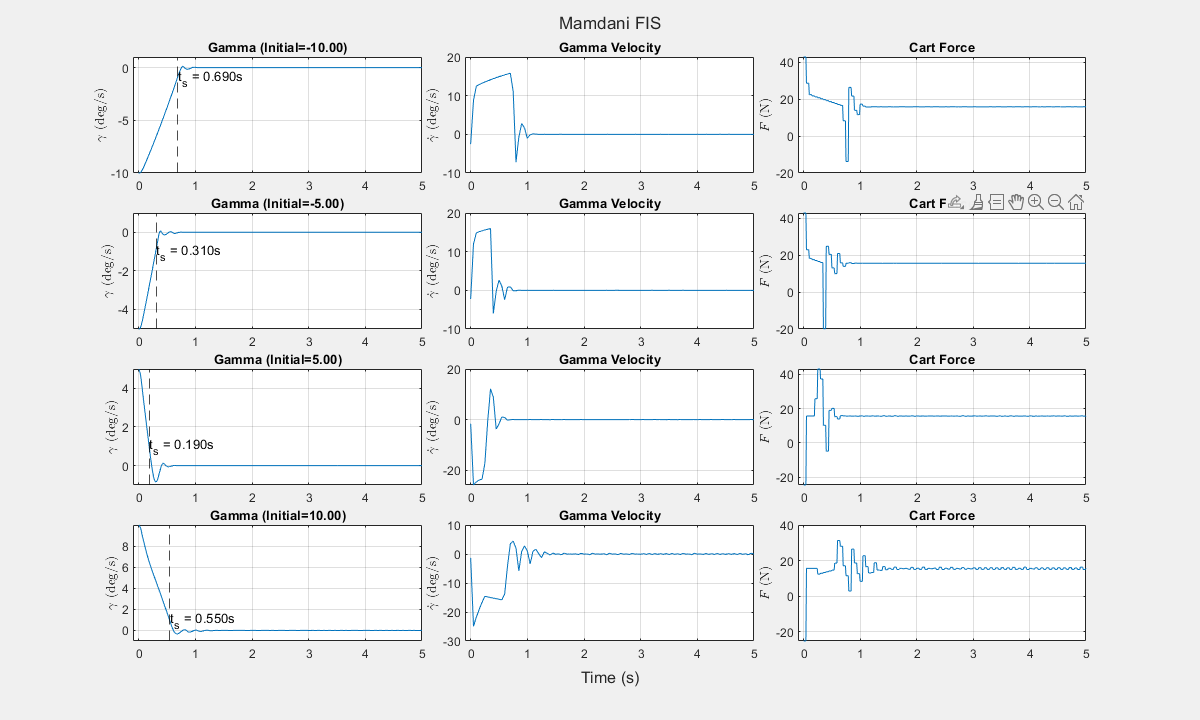

function f = runFis(fis, p_err, d_err)
    % f = evalfis(...);
end

### 2.6 Run Code

Run the code in section 2 using Ctrl+Enter. Fix any errors that show up. Any changes to the MFs during tuning will require this section to be re-run with Ctrl+Enter.

fis = initFis(constants, params); % call the function

% plot the MFs
fig1 = figure(1);
set(fig1, 'Visible', 'on')
tiledlayout(1, 3, 'TileSpacing', 'Tight');
fig1.Position = [20, 20, 1600, 240];

nexttile;
plotmf(fis, 'input', 1, 1000);
grid on;

nexttile;
plotmf(fis, 'input', 2, 1000);
grid on;

nexttile;
plotmf(fis, 'output', 1, 1000);
grid on;

## 3. Simulation

By adjusting the membership functions and rule table, and ensuring that all code from the previous section are correct, your task is to:

- Have a settling time of 1s or less for all starting angles $\gamma_0 \in\{-10^\circ, -5^\circ, 5^\circ, 10^\circ\}$. The settling time can be seen in the figure as $t_s$.

- Have negligible overshoot in $\gamma$.

- Steady state $\gamma$ should be as close to zero as possible. Hint: adjust the force MFs.

- Ignore the cart's linear velocity.

**You can ignore the code in this section**. There are basically three parts. 

- The first part programs the function `simFis()` to simulate the physics of the inverted pendulum on a cart on a slope using the Euler Lagrange formulation for a specified initial $\gamma$, and analyses the settling time and steady state error.

- The second part runs the function `simFis()` for all the initial gammas specified in `constants.START_GAMMAS` and collects the results. 

- The third part plots the results.

% start_gamma is in degrees.
function [T, PS, PV, F, CS, CV, settling_time, last_p_err] = simFis(fis, constants, start_gamma)
T = 0:constants.DT:constants.T_TOTAL;
CS = nan(size(T));
CV = nan(size(T));
PS = nan(size(T)); % gamma
PV = nan(size(T));
F = nan(size(T));

f = 0;
theta = deg2rad(start_gamma - constants.PHI);
pv = 0;
cs = 0;
cv = 0;

settling_time = nan;
last_p_err = nan;

for i = 1:numel(T)
    C_THETA = cos(theta);
    S_THETA = sin(theta);

    % From euler lagrange formulation
    tmp_a = f - 0.5*pv*pv*S_THETA - constants.WEIGHT - cv*constants.KF_CART;
    tmp_b = -constants.G * (S_THETA*constants.C_PHI + C_THETA*constants.S_PHI) - pv*constants.KF_PEND;
    tmp_denom = constants.MML76 - 0.5*C_THETA*C_THETA;
    ca = (constants.L76*tmp_a + 0.5*C_THETA*tmp_b) / tmp_denom;
    pa = (-C_THETA*tmp_a + constants.M_TOTAL*tmp_b) / tmp_denom;

    % linear approximation
    theta = theta + pv*constants.DT + 0.5*pa*constants.DT2;
    ps = theta + deg2rad(constants.PHI);
    pv = pv + pa*constants.DT;
    cs = cs + cv*constants.DT + 0.5*ca*constants.DT2;
    cv = cv + ca*constants.DT;

    % controller
    if mod(i-1, constants.CTRL_STEP) == 0
        [p_err, d_err] = getErrors(rad2deg(ps), rad2deg(pv));
        p_err = p_err + randn()*1e-4; % corrupt with noise
        d_err = d_err + randn()*1e-4; % corrupt with noise

        if p_err < constants.P_ERR_UNI(1) || p_err > constants.P_ERR_UNI(2) || ...
            d_err < constants.D_ERR_UNI(1) || d_err > constants.D_ERR_UNI(2)
            last_p_err = p_err; 
            settling_time = nan; 
            fprintf("Re-tune: System is unstable and out of universe\n");
            break;
        end

        f = runFis(fis, p_err, d_err);

        % saturate force like real world system
        f = clip(f, -constants.F_MAX, constants.F_MAX);
    end
    CS(i) = cs;
    CV(i) = cv;
    PS(i) = ps;
    PV(i) = pv;
    F(i) = f;
end

PS = rad2deg(PS);
PV = rad2deg(PV);

% If all variables are within their universes (i.e. not too unstable),
% reevaluate steady_state and settling_time
if (isnan(last_p_err))
    last_p_err = -PS(end); % good enough to use the last value, especially since this will catch any mildly unstable systems.
    for i = numel(T):-1:1
        ps = PS(i);
        if (ps < -constants.GAMMA_SET || ps > constants.GAMMA_SET)
            if (i < numel(T))
                settling_time = T(i+1);
            end
            break
        end
    end
end
end

% ================= run the simulation for all START_GAMMAS
results = [];
for i = 1:numel(constants.START_GAMMAS)
    r = struct();
    [r.time, r.gamma, r.gamma_vel, ...
        r.force, r.cart_pos, r.cart_vel, ...
        r.settling_time, r.last_p_err] ...
        = simFis(fis, constants, constants.START_GAMMAS(i));
    results = [results, r];
end

% ===================== plot
fig2 = figure(2);
set(fig2, 'Visible', 'on');
fig2.Position = [0, 0, 1200, 720];
tld = tiledlayout(numel(constants.START_GAMMAS), 3, TileSpacing="tight");
title(tld, "Mamdani FIS");
xlabel(tld, "Time (s)");
for i = 1:numel(constants.START_GAMMAS)
    r = results(i);

    nexttile
    plot(r.time, r.gamma)
    start_gamma = constants.START_GAMMAS(i);
    title(sprintf('Gamma (Initial=%.2f)', start_gamma));
    if (~isnan(r.settling_time))
        xline(r.settling_time, '--k');
        text(r.settling_time, sign(start_gamma) * constants.GAMMA_SET, sprintf('t_s = %.3fs', r.settling_time))
    end
    grid on
    xlim([-0.1, r.time(end)])
    if start_gamma > 0; ylim([-constants.GAMMA_SET, inf]);
    else; ylim([-inf, constants.GAMMA_SET]);
    end

    ylabel("$\gamma$ (deg/s)", Interpreter="latex");

    nexttile
    plot(r.time, r.gamma_vel)
    title('Gamma Velocity');
    grid on
    xlim([-0.1, r.time(end)])
    ylabel("$\dot{\gamma}$ (deg/s)", Interpreter="latex");

    nexttile
    plot(r.time, r.force)
    title('Cart Force');
    grid on
    xlim([-0.1, r.time(end)])
    ylabel("$F$ (N)", Interpreter="latex");
end

## 4. Export Figures

You can save the figures into images (pngs) by running the code below. The images will be saved in the current folder.

% exportgraphics(fig1,'MFs.pdf','BackgroundColor','none','ContentType','vector');
% exportgraphics(fig2,'tuned.pdf','BackgroundColor','none','ContentType','vector');

fprintf("Images saved to %s\n", pwd());
exportgraphics(fig1,'MFs.png','BackgroundColor','white');
exportgraphics(fig2,'results.png','BackgroundColor','white');